train_dataset = train;
test_dataset = test;

train_dataset = fillmissing(train_dataset,'linear');
test_dataset = fillmissing(test_dataset,'linear');


train_dataset(train_dataset.pm2p5_x > 500, :) = [];
train_dataset(train_dataset.pm2p5_y > 500, :) = [];

test_dataset(test_dataset.pm2p5_x > 500, :) = [];
test_dataset(test_dataset.pm2p5_y > 500, :) = [];
train_dataset.month = month(train_dataset.valid_at);
test_dataset.month = month(test_dataset.valid_at);

input_features = {'pm1'; 'pm2p5_x'; 'pm4'; 'pm10'; 'relative_humidity'; 'temperature'; 'wind_speed'; 'pressure'};
% input_features_num_mf = [3, 3, 3, 3, 2, 3, 3, 3];
input_features_num_mf = [2, 6, 2, 2, 2, 2, 2, 2];
% input_features_num_mf = [2, 6, 2, 2, 2, 3, 3, 3];

maxK = length(input_features);

% Assuming you have input_features, table1, and table2

% Initialize an empty table to store the rows with minimum values
minRowsTable = table();
maxRowsTable = table();

% Iterate over each feature
for i = 1:numel(input_features)
    % Get the column index for the current feature
    featureIndex = find(strcmp(test_dataset.Properties.VariableNames, input_features{i}));
    
    % Find the row index with the minimum value for the current feature
    [~, minRowIndex] = min(test_dataset.(featureIndex));
    [~, maxRowIndex] = max(test_dataset.(featureIndex));

    % Extract the row with the minimum value for the current feature
    minRow = test_dataset(minRowIndex, :);
    maxRow = test_dataset(maxRowIndex, :);

    % Append the extracted row to minRowsTable
    minRowsTable = [minRowsTable; minRow];
    maxRowsTable = [maxRowsTable; maxRow];

    % Remove the extracted row from table2
    test_dataset(minRowIndex, :) = [];
    test_dataset(maxRowIndex, :) = [];
end

% Append the rows with minimum values to table1
train_dataset = [train_dataset; minRowsTable];
train_dataset = [train_dataset; maxRowsTable];

% Extract data from tables
data1 = table2array(train_dataset(:,input_features));
data2 = table2array(test_dataset(:,input_features));

% Concatenate data from both tables
all_data = [data1; data2];

% Perform min-max normalization
min_vals = min(all_data);
max_vals = max(all_data);

normalized_data1 = (data1 - min_vals) ./ (max_vals - min_vals);
normalized_data2 = (data2 - min_vals) ./ (max_vals - min_vals);

% Convert normalized data back to tables
normalized_table1 = array2table(normalized_data1, 'VariableNames', train_dataset(:,input_features).Properties.VariableNames);
normalized_table2 = array2table(normalized_data2, 'VariableNames', test_dataset(:,input_features).Properties.VariableNames);

train_dataset.pm2p5_x_original = train_dataset.pm2p5_x;
test_dataset.pm2p5_x_original = test_dataset.pm2p5_x;

% Replace normalized data columns in original tables
for i = 1:size(data1, 2)
    train_dataset.(train_dataset(:,input_features).Properties.VariableNames{i}) = normalized_data1(:, i);
end

for i = 1:size(data2, 2)
    test_dataset.(test_dataset(:,input_features).Properties.VariableNames{i}) = normalized_data2(:, i);
end


complete_train_table = train_dataset(:,{'valid_at'; 'sensor_id'; 'pm1'; 'pm2p5_x'; 'pm4'; 'pm10'; 'relative_humidity'; 'temperature'; 'wind_speed'; 'pressure'; 'pm2p5_y'; 'pm2p5_x_original'});
complete_test_table = test_dataset(:,{'valid_at'; 'sensor_id'; 'pm1'; 'pm2p5_x'; 'pm4'; 'pm10'; 'relative_humidity'; 'temperature'; 'wind_speed'; 'pressure'; 'pm2p5_y'; 'pm2p5_x_original'});

-------------------------------


    "pm2p5_x"    "relative_humidity"    "temperature"



ANFIS info:
	Number of nodes: 74
	Number of linear parameters: 96
	Number of nonlinear parameters: 30
	Total number of parameters: 126
	Number of training data pairs: 28128
	Number of checking data pairs: 0
	Number of fuzzy rules: 24


Start training ANFIS ...

1 	 9.03833
2 	 9.01089
3 	 8.97986
4 	 8.97153
Step size increases to 0.011000 after epoch 5.
5 	 8.95095
6 	 8.91517
7 	 8.92772
8 	 8.92553
9 	 8.91515
10 	 8.92059
11 	 8.90453
12 	 8.91793
Step size decreases to 0.009900 after epoch 13.
13 	 8.89719
14 	 8.91576
15 	 8.87989
16 	 8.91284
Step size decreases to 0.008910 after epoch 17.
17 	 8.87665
18 	 8.91071
19 	 8.86405
20 	 8.90229
Step size decreases to 0.008019 after epoch 21.
21 	 8.88232
22 	 8.8971
23 	 8.86384
24 	 8.89562
Step size decreases to 0.007217 after epoch 25.
25 	 8.8628
26 	 8.89526
27 	 8.85345
28 	 8.8926
Step size decreases to 0.006495 after epoch 29.
29 	 8.85697
30 	 8.8908
31 	 8.84981
32 	 8.88739
Step size decreases to 0.005846 after epoch 33.


outputFIS =   sugfis with properties:

                       Name: "fis"
                  AndMethod: "prod"
                   OrMethod: "max"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
    DisableStructuralChecks: 0
                     Inputs: [1×3 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×24 fisrule]

	See 'getTunableSettings' method for parameter optimization.


outputFIS =   sugfis with properties:

                       Name: "fis"
                  AndMethod: "prod"
                   OrMethod: "max"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
    DisableStructuralChecks: 0
                     Inputs: [1×3 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×24 fisrule]

	See 'getTunableSettings' method for parameter optimization.


Train


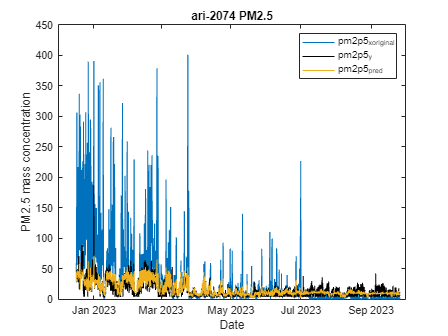

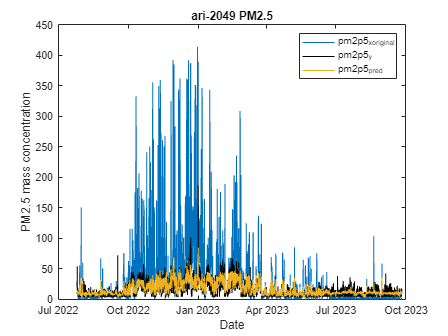

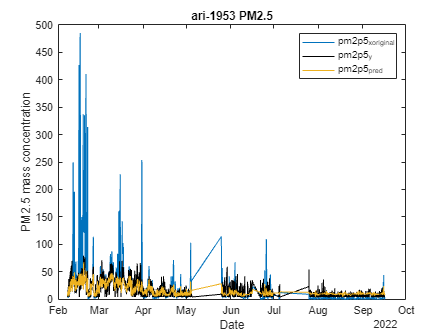

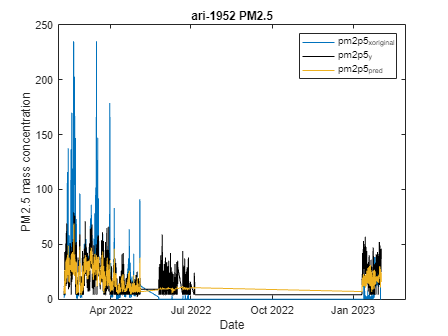

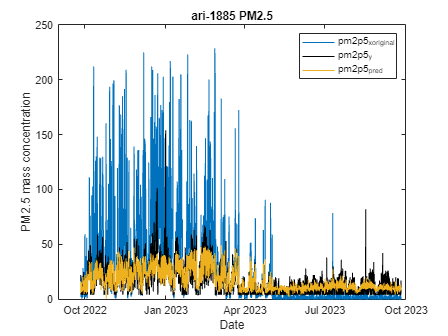

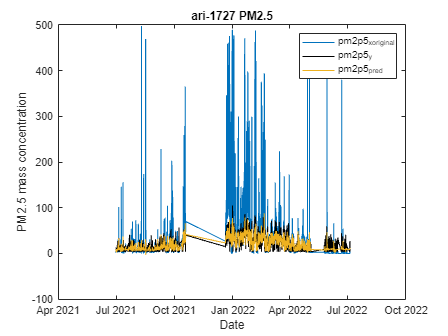

    SensorID      R2        MAE       MSE       RMSE 
    ________    _______    ______    ______    ______

    "-2074"     0.60985    5.4477    67.279    8.2023
    "-2049"      0.6233    5.4777    62.686    7.9175
    "-1953"     0.60461    6.4033    78.108    8.8379
    "-1952"     0.42395    8.3123    121.86    11.039
    "-1885"      0.5833    5.9387    71.783    8.4725
    "-1727"     0.61312    7.4959    103.79    10.188
    "all"       0.60399    6.2017    78.065    8.8354



Test


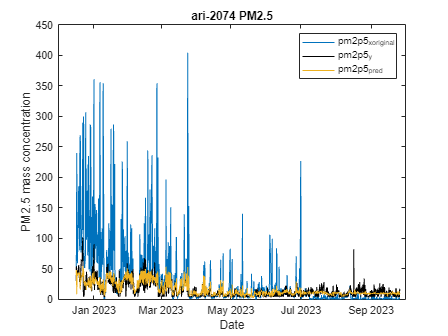

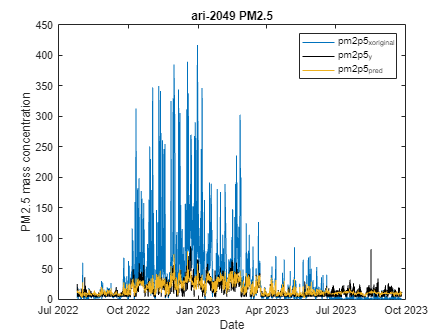

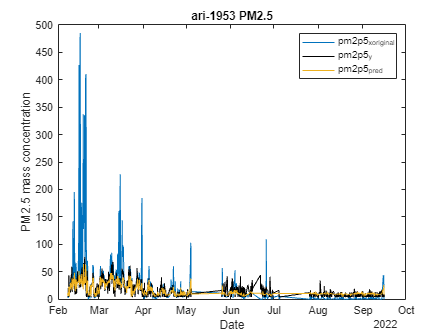

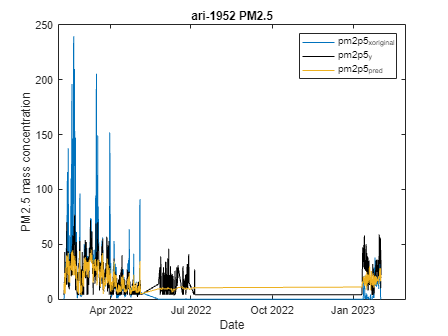

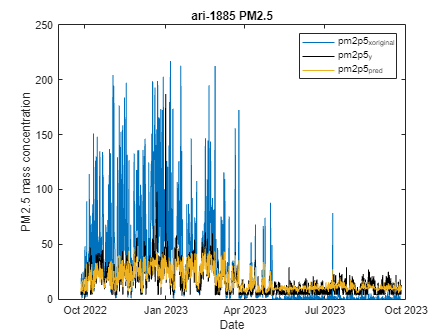

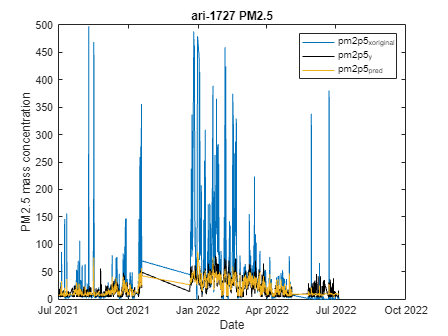

    SensorID      R2        MAE       MSE       RMSE 
    ________    _______    ______    ______    ______

    "-2074"     0.59116    5.7535    74.188    8.6133
    "-2049"     0.58418    5.5061    60.878    7.8024
    "-1953"     0.59324     6.434     78.33    8.8504
    "-1952"     0.40986    8.4822    130.61    11.429
    "-1885"     0.54939    5.9956    78.403    8.8545
    "-1727"     0.61314    7.2844    97.778    9.8883
    "all"       0.58282    6.2801    80.431    8.9683



    "pm2p5_x"

    "relative_humidity"

    "temperature"




% Define the specific combinations
specified_combinations =  {
    ["pm2p5_x"],
    ["pm1", "pm2p5_x", "pm4", "pm10"],
    ["pm2p5_x", "relative_humidity"]
    ["pm1", "pm2p5_x", "pm4", "pm10", "relative_humidity"],
    ["pm2p5_x", "pm10", "relative_humidity"],
    ["pm2p5_x", "relative_humidity", "temperature"],
    ["pm2p5_x",  "pm10", "relative_humidity", "temperature"],
    ["pm2p5_x", "relative_humidity", "temperature", "pressure"],
    ["pm2p5_x", "pm10", "relative_humidity", "temperature", "pressure"],
    ["pm2p5_x", "relative_humidity", "temperature", "wind_speed"],
    ["pm2p5_x", "relative_humidity", "temperature", "pressure", "wind_speed"],
    ["pm2p5_x", "pm10", "relative_humidity", "temperature", "pressure", "wind_speed"]
};

% Generate and display all combinations for different values of k
for i = 1:size(specified_combinations, 1)
    currentCombination = specified_combinations{i};
    
    currentCombination_mf = input_features_num_mf(ismember(input_features, currentCombination));
    % display(currentCombination_mf);
     % Perform something for combinations containing pm2p5_X
    disp('-------------------------------');
    disp(currentCombination);

    % options = genfisOptions('SubtractiveClustering');
    options = genfisOptions('GridPartition');
    options.InputMembershipFunctionType = 'trimf';
    options.NumMembershipFunctions = currentCombination_mf;
   

    outputFIS = fitFuzzySystem(train_dataset(:,currentCombination), train_dataset(:,{'pm2p5_y'}), options);
    
    outputFIS
    outputFIS
    disp('Train');
    evalFuzzySystem(outputFIS, complete_train_table, currentCombination);
    disp('Test');
    evalFuzzySystem(outputFIS, complete_test_table, currentCombination);
    
end